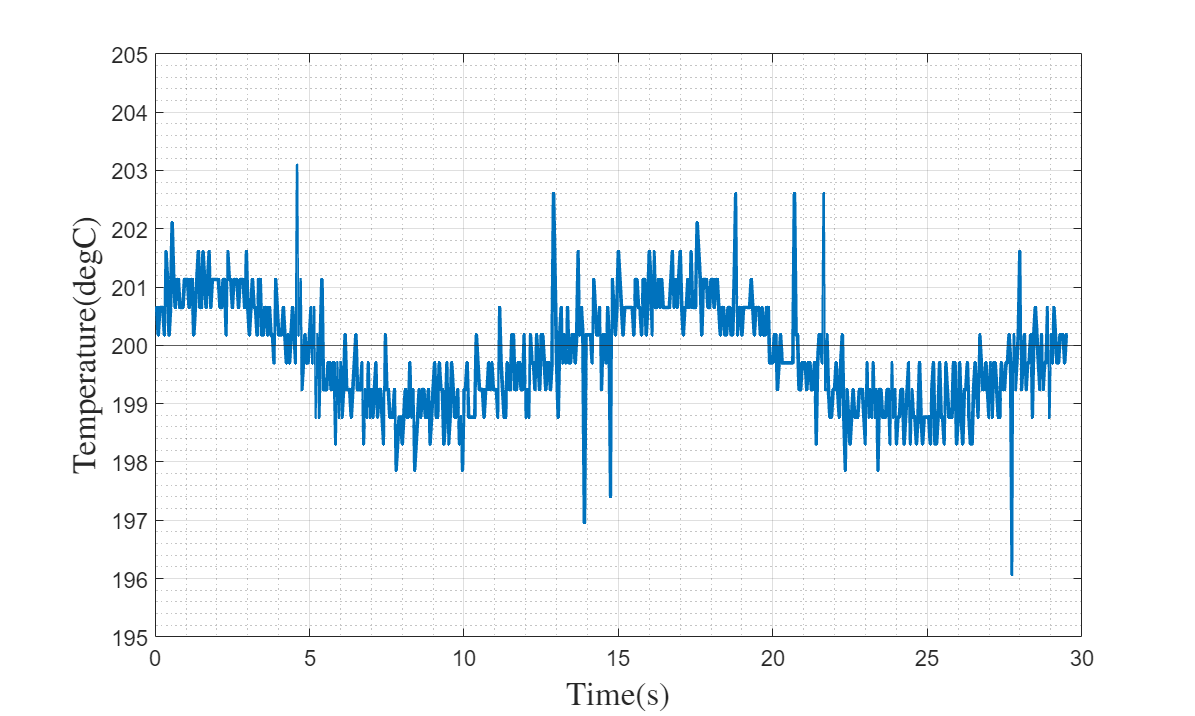

heatUp1 = importdata('fanTemp3.bin');
heatUp2 = importdata('coldTest2.bin');
heatUp3 = importdata('coldTest3.bin');

heatUp = [heatUp1] + 19.8;
timeVec = [0.05:0.05:29.55]';

plot(timeVec, heatUp)
hold on
grid on
grid minor
set(gcf,'position',[0,0,1000,600])
set(findall(gca, 'Type', 'Line'),'LineWidth',2)
set(gca,'fontsize',12)
xlabel('Time(s)','fontsize',18,'fontweight','bold','interpreter','latex');
ylabel('Temperature(degC)','fontsize',18,'fontweight','bold','interpreter','latex');
yline(200)
xlim([0 30])
ylim([195 205])
hold off

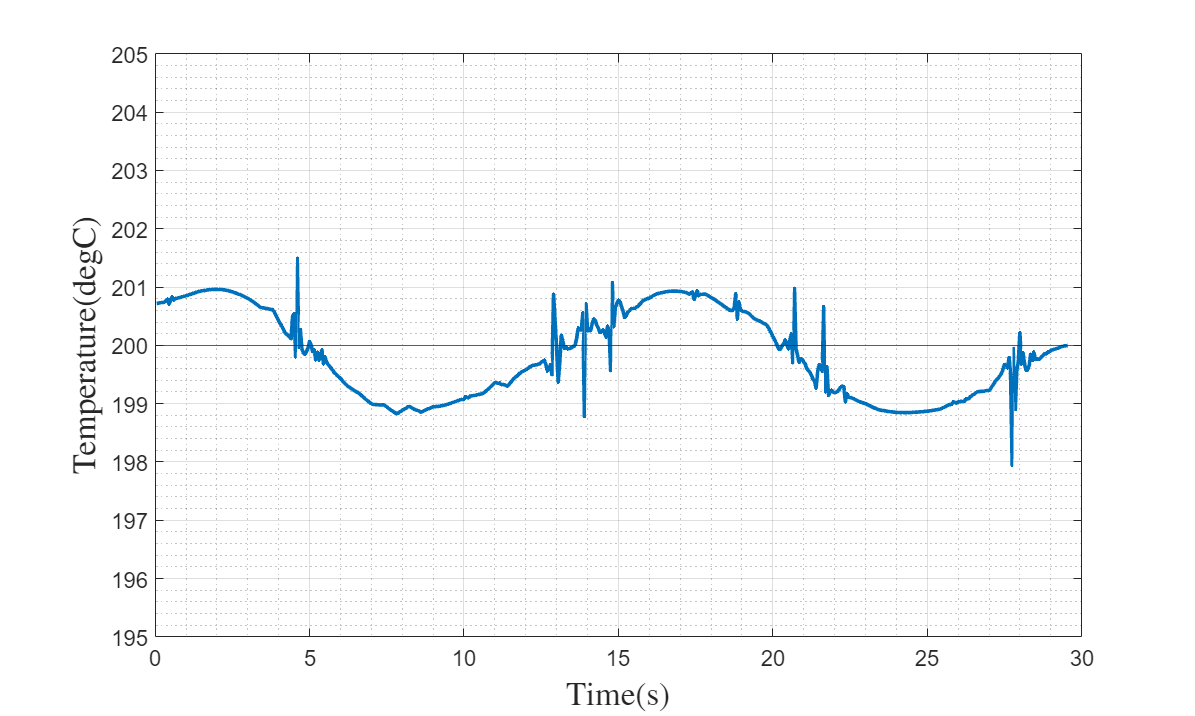

heatD = wdenoise(heatUp,'Wavelet','sym8','DenoisingMethod','SURE','ThresholdRule','Soft');
heatDD = wdenoise(heatD,3,'Wavelet','db3',...
    'DenoisingMethod','UniversalThreshold',...
    'ThresholdRule','Soft',...
    'NoiseEstimate','LevelDependent');

plot(timeVec, heatDD)
hold on
grid on
grid minor
set(gcf,'position',[0,0,1000,600])
set(findall(gca, 'Type', 'Line'),'LineWidth',2)
set(gca,'fontsize',12)
xlabel('Time(s)','fontsize',18,'fontweight','bold','interpreter','latex');
ylabel('Temperature(degC)','fontsize',18,'fontweight','bold','interpreter','latex');
yline(200)
xlim([0 30])
ylim([195 205])
hold off